% 方法一
clear;
load hall;
load JpegCoeff;
im = double(hall_gray)-128;

% 补全图片大小为8的倍数大小
[h,w] = size(im);
H = ceil(h/8)*8;
W = ceil(w/8)*8;
img = zeros(H,W);
img(1:h,1:w)=im;

h_seq = H/8;
w_seq = W/8;
result = zeros(64,h_seq*w_seq);
count = 1;
for i = 1:h_seq
    for j = 1:w_seq
        cur = img(i*8-7:i*8,j*8-7:j*8); % 截取
        cur = dct2(cur);                % DCT
        cur = round(cur./QTAB);         % 量化
        cur = (zigzag(cur))';           % zigzag扫描
        result(:,count) = cur;          % 排列
        count = count+1;
    end
end

% 隐藏
info_size = H*W;
blocks_size = info_size/64;
info = randi([0,1],[1,info_size]);
info_result = result;
for i = 1:1:64
    for j = 1:1:blocks_size
        if info(blocks_size*i+j-blocks_size)==1 && mod(result(i,j),2)==0
            info_result(i,j) = info_result(i,j)+1;
        elseif info(blocks_size*i+j-blocks_size)==0 && mod(result(i,j),2)==1
            info_result(i,j) = info_result(i,j)-1;
        end
    end
end

c_DC = info_result(1,1:blocks_size);
c_AC_All = info_result(2:64,1:blocks_size);

% 反量化&DCT逆变换
[~,num_block] = size(c_DC);
blocks = zeros(8,8,num_block);
for i = 1:1:num_block
    blocks(:,:,i)=antizigzag([c_DC(i),c_AC_All(:,i)']); % 量化值
    blocks(:,:,i)=blocks(:,:,i).*double(QTAB); 
    blocks(:,:,i)=idct2(blocks(:,:,i));
end

% 拼接
info_img = zeros(H,W);
for i = 1:1:H/8
    for j = 1:1:W/8
        info_img(8*i-7:8*i,8*j-7:8*j)=blocks(:,:,W*(i-1)/8+j);
    end
end
info_img = uint8(info_img + 128);

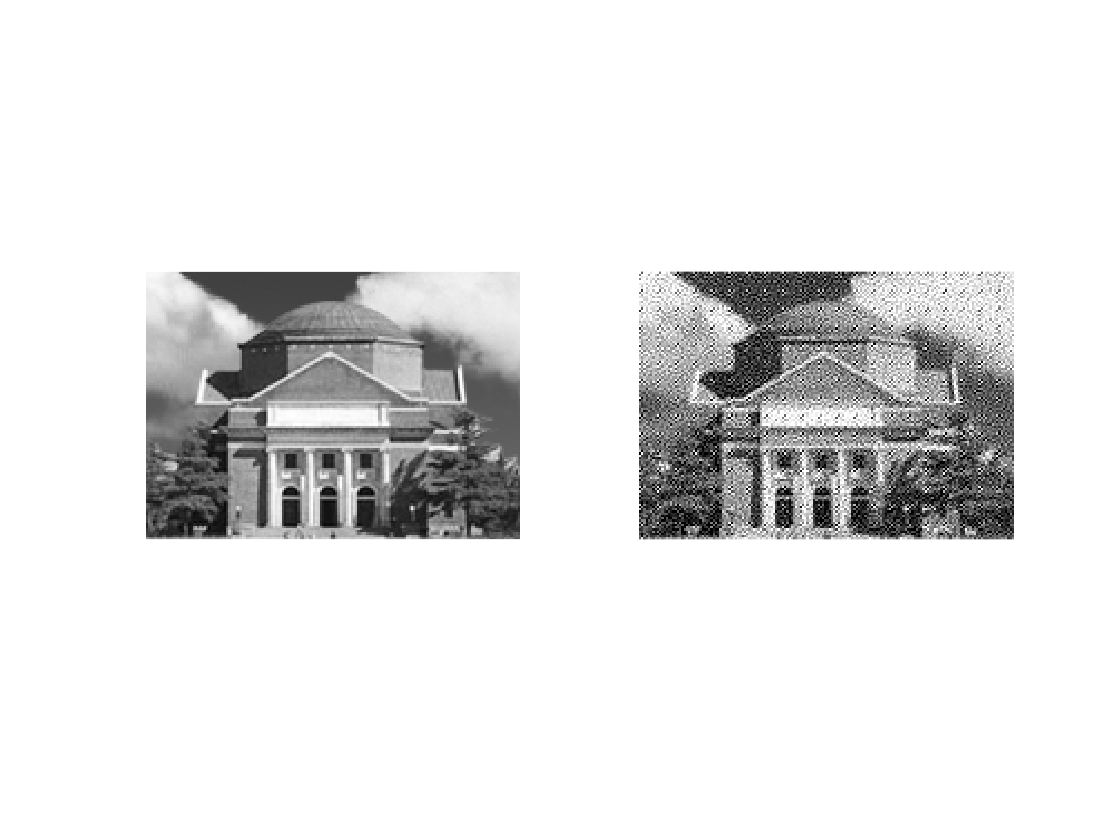

% 显示图象
subplot(1,2,1);
imshow(hall_gray);
subplot(1,2,2);
imshow(info_img);

% 计算压缩比
[DC_code,AC_code,~,~]=compress(info_img);
[~,com_bit] = size([DC_code,AC_code]);
ori_bit = H*W*8;
com_rat = ori_bit/com_bit

com_rat = 2.8339

% 计算PSNR
MSE = 0;
for i = 1:1:H
    for j = 1:1:W
        MSE = MSE + (double(info_img(i,j))-double(hall_gray(i,j))).^2;
    end
end
MSE = MSE/(H*W);

PSNR = 10*log10((255^2)/MSE)

PSNR = 15.4372